# Transformada de Laplace

## Transformada Bilateral


$$X\left(s\right)=\int_{-\infty }^{\infty } x\left(t\right)e^{-\textrm{st}} \textrm{dt}$$



$$s=\sigma +j\omega$$


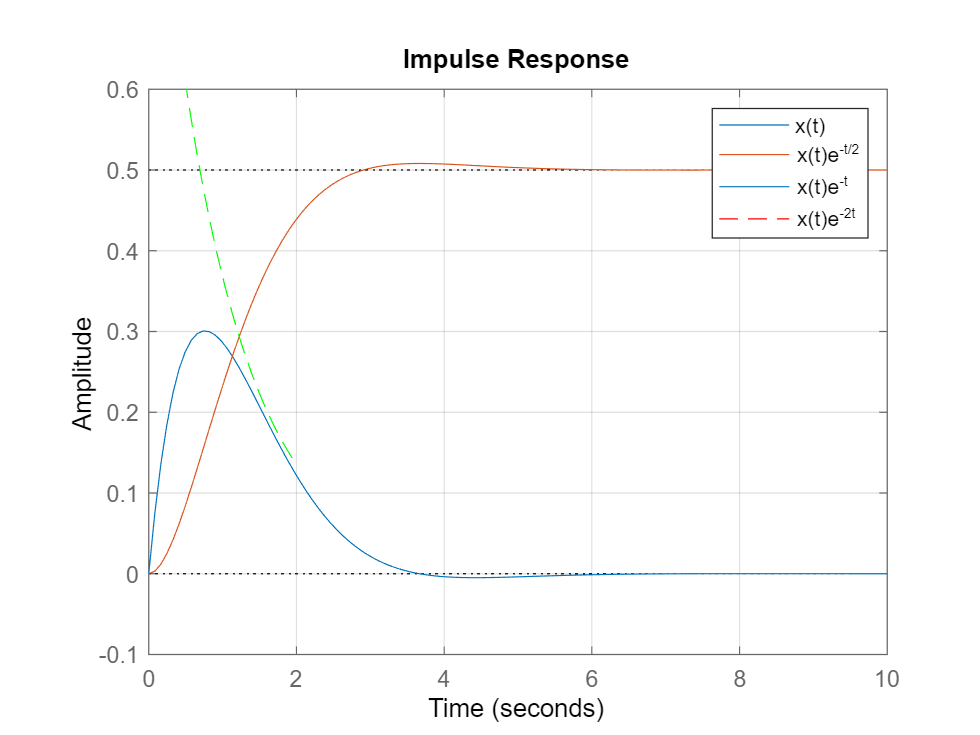

t = -0.5:0.001:2;
u = @(t) t>=0;
x = @(t) exp(t).*u(t);
figure(1)
plot(t,x(t));
grid minor
hold on
xa = @(t,sigma) x(t).*exp(-sigma*t);
plot(t,xa(t,0.5),'r--',t,xa(t,1),'y--',t,xa(t,2),'g--')
legend({'x(t)','x(t)e^{-t/2}','x(t)e^{-t}','x(t)e^{-2t}'})

### Ejemplo 1


$$x\left(t\right)=e^{-\textrm{at}} u\left(t\right)$$



$$X\left(s\right)=\int_{-\infty }^{\infty } e^{-\textrm{at}} u\left(t\right)e^{-\textrm{st}} \textrm{dt}$$



$$X\left(s\right)=\int_0^{\infty } e^{-\textrm{at}} e^{-\textrm{st}} \textrm{dt}$$



$$X\left(s\right)=\int_0^{\infty } e^{-\left(a+s\right)t} \textrm{dt}$$



$$X\left(s\right)=-\frac{1}{a+s}\left(e^{-\left(a+s\right)\infty } -e^{-\left(a+s\right)0} \right)$$


Si $\textrm{Re}\left\lbrace a+s\right\rbrace =a+\sigma \;\le 0$ entonces la integral diverge pero si $\textrm{Re}\left\lbrace a+s\right\rbrace =a+\sigma \;>0$ la integral converge a:


$$X\left(s\right)=\frac{1}{s+a}$$


Es decir que la región de convergencia para esta función es $\sigma \;>-a$

### Ejemplo 2


$$x\left(t\right)={-e}^{-\textrm{at}} u\left(-t\right)$$



$$X\left(s\right)=\int_{-\infty }^{\infty } -e^{-\textrm{at}} u\left(-t\right)e^{-\textrm{st}} \textrm{dt}$$



$$X\left(s\right)=\int_{-\infty }^0 -e^{-\textrm{at}} e^{-\textrm{st}} \textrm{dt}$$



$$X\left(s\right)=\int_{-\infty }^0 -e^{-\left(a+s\right)t} \textrm{dt}$$



$$X\left(s\right)=-\frac{1}{a+s}\left({-e}^{-\left(a+s\right)0} +e^{\left(a+s\right)\infty } \right)$$


Si $\textrm{Re}\left\lbrace a+s\right\rbrace =a+\sigma \;\ge 0$ entonces la integral diverge pero si $\textrm{Re}\left\lbrace a+s\right\rbrace =a+\sigma <0$ la integral converge a:


$$X\left(s\right)=\frac{1}{s+a}$$


Es decir que la región de convergencia para esta función es $\sigma <-a$

### Ejemplo 3


$$X\left(s\right)=\int_{-\infty }^{\infty } x\left(t\right)e^{-\textrm{st}} \textrm{dt}$$



$$x\left(t\right)=u\left(t+a\right)-u\left(t-a\right),a>0$$



$$X\left(s\right)=\int_{-\infty }^{\infty } \left(u\left(t+a\right)-u\left(t-a\right)\right)e^{-\textrm{st}} \textrm{dt}$$



$$X\left(s\right)=\int_{-a}^a e^{-\textrm{st}} \textrm{dt}$$



$$X\left(s\right)=-\frac{1}{s}\left(e^{-\textrm{sa}} -e^{\textrm{sa}} \right)$$



$$X\left(s\right)=\frac{e^{\textrm{sa}} -e^{-\textrm{sa}} }{s}$$


La cual converge para cualquier $s\not= 0$ es decir que la región de convergencia para esta función es todo el plano complejo (salvo el 0)

## Función de Transferencia

De manera análoga al concepto de **respuesta en frecuencia** trabajado con la transformada de Fourier, se tiene el concepto de **función de transferencia** cuando se trabaja con transformada de Laplace (con sistemas LTI). Esta al igual que en el caso anterior permite simplificar los cálculos de las respuestas de sistemas aprovechando la propiedad de convolución:


$$y\left(t\right)=x\left(t\right)*h\left(t\right)$$



$$Y\left(s\right)=X\left(s\right)H\left(s\right)$$



$$y\left(t\right)=L^{-1} \left\lbrace X\left(s\right)H\left(s\right)\right\rbrace$$


Por otro lado, es posible caracterizar un sistema LTI a partir de cualquier par entrada-salida conocido (salvo $x\left(t\right)=0$) con la función de transferencia


$$H\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}$$



$$h\left(t\right)=L^{-1} \left\lbrace H\left(s\right)\right\rbrace =L^{-1} \left\lbrace \frac{Y\left(s\right)}{X\left(s\right)}\right\rbrace$$


### Sistemas dinámicos

Para los sistemas descritos por ecuaciones diferenciales se aprovecha la propiedad de derivación $\frac{d}{\mathrm{dt}}x\left(t\right)\overset{L}{\leftrightarrow} sX\left(s\right)$


$$\ddot{y} \left(t\right)+b\dot{y} \left(t\right)+ky\left(t\right)=x\left(t\right)$$



$$s^2 Y\left(s\right)+bsY\left(s\right)+kY\left(s\right)=X\left(s\right)$$



$$H\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}=\frac{1}{s^2 +bs+k}$$


dependiendo de los parámetros $b$ y $k$ podemos tener distintos tipos de comportamiento en el sistema ya que estos determinan la ubicación de los polos del sistema:


$$s=\frac{-b\pm \sqrt{b^2 -4k}}{2}$$


**Nota: **por simplicidad asumiremos el caso de la trasnformada unilateral, es decir que la región de convergencia será a la derecha del polo más grande (más positivo) del sistema.

De aquí se pueden identificar varios casos de interés, en particular

$b=0,k>0$ este caso es conocido como no amortiguado (o críticamente amortiguado), en esta situación los polos siempre serán imaginarios con lo que la salida será una oscilación permanente.

$b^2 >4k,k>0$ este caso es conocido como sobre amortiguado, en esta situación los polos siempre seran reales y la salida serán exponenciales sin oscilación.

$0<b^2 <4k,k>0$ este caso es conocido como sub amortiguado, en esta situación los polos siempre serán complejos conjugados con lo que la salida será una oscilación modulada por una exponencial.

podemos visualizar el comportamiento de la respuesta al impulso y al escalón del sistema variando parámetros en la siguiente sección:

b =1;
k = 2;
disp(b^2-4*k)

    -7



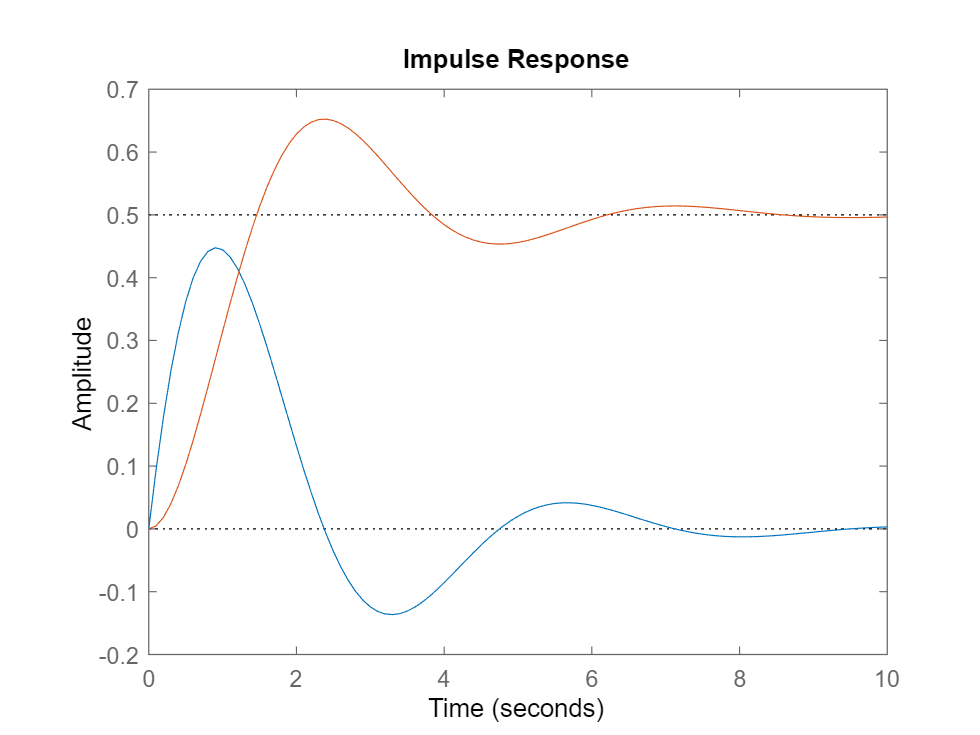

s = tf('s');
H = 1/(s^2+b*s+k);
figure()
impulse(H,10)
hold on
step(H, 10)

## Teoremas del valor inicial y del valor final


$$x\left(0^+ \right)=\lim_{s\to \infty \;} \textrm{sX}\left(s\right)$$
 


$$x_{\mathrm{ss}} :=\lim_{t\to \infty \;} x\left(t\right)=\lim_{s\to 0} \mathrm{sX}\left(s\right)$$


*El teorema del valor final requiere que $X\left(s\right)$ sea estable.

## Estabilidad y causalidad

- La región de convergencia de la función de transferencia de un sistema **estable** incluye el eje imaginario

- La región de convergencia de la función de transferencia de un sistema **causal** es un semiplano derecho